
clear all
close all

addpath('data')
addpath('subfunctions')
load catchingData

Lets have a look at hte data we've just imported!

etData

etData =            viewPos_fr_XYZ: [2848x3 double]
      cycEyeInHead_fr_XYZ: [2848x3 double]
        leftEyePos_fr_XYZ: [2848x3 double]
           ballPos_fr_XYZ: [2848x3 double]
                   IPD_fr: [1x2848 double]
           viewMat_fr_4x4: {2848x1 cell}
             eventFlag_fr: {1x2848 cell}
       rightEyePos_fr_XYZ: [2848x3 double]
           blockNumber_fr: [1x2848 int64]
    calibrationPos_fr_XYZ: [2848x3 double]
           trialNumber_fr: [1x2848 int64]
             frameTime_fr: [1x2848 double]
     leftEyeInHead_fr_XYZ: [2848x3 double]
    rightEyeInHead_fr_XYZ: [2848x3 double]
    calibrationCounter_fr: [1x2848 int64]
                   IOD_fr: [1x2848 double]
          eyeTimeStamp_fr: [1x2848 int64]


The majority of data about positions/orientations was exported from Vizard, and follows Vizard conventions.  The SMI data is untouched, straight from the tracker.  We plan to plot using the "Plotly" module.  So, here are the relevant coordinate systems.

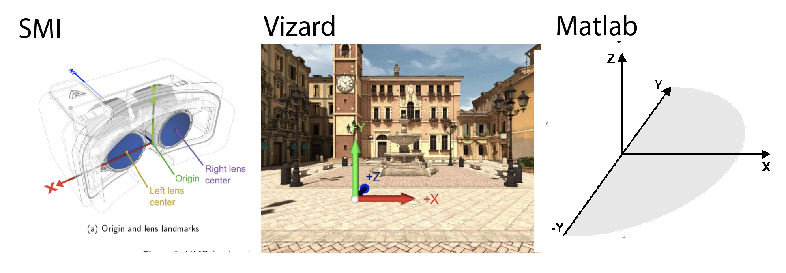

Notice that the the X axis is flipped between Vizard and SMI.  We will have to account for that.

etData.cycEyeInHead_fr_XYZ(:,1) = -etData.cycEyeInHead_fr_XYZ(:,1);

That's great, but it's hard to interpret three-dimensional unit vectors without 3D figures, and we're not ready for that yet.  How about we use spherical coordinates, instead?

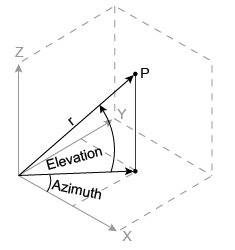

The equations are fairly straightforward, if you remember your trig, and know your coordinate systems (see the first figure in this script). We're in vizard coordinates, so opposite is the X component, and adjacent is the Z component.  

degrees azimuth = arctan(X/Z) * (180/pi) 

Similarly,

degrees elevation = arctan(U/Z) * (180/pi)  


for frIdx = 1:length(etData.cycEyeInHead_fr_XYZ)
    
    cycEyeInHead_fr_XYZ(frIdx,:) = etData.cycEyeInHead_fr_XYZ(frIdx,:);
   
    eihAzimuthDeg_fr(frIdx) = rad2deg(atan(cycEyeInHead_fr_XYZ(frIdx,1)./cycEyeInHead_fr_XYZ(frIdx,3)));
    eihElevationDeg_fr(frIdx) = rad2deg(atan(cycEyeInHead_fr_XYZ(frIdx,2)./cycEyeInHead_fr_XYZ(frIdx,3)));
    
end




Lets get the index for a single trial, and plot!

idx = find(etData.trialNumber_fr == 5);

trNum = 1;

startFrame = min(find(etData.trialNumber_fr == trNum))

startFrame = 286


% End on the trial frame when ball hits paddle, floor, or when the last trialFrames == trNum.
endFrame = min( [intersect(find(etData.trialNumber_fr == trNum),find(strcmp(etData.eventFlag_fr,'ballOnPaddle')))...
                 intersect(find(etData.trialNumber_fr == trNum),find(strcmp(etData.eventFlag_fr,'ballOnFloor'))) ...
                 min( find(etData.trialNumber_fr == trNum,1,'last') )])

endFrame = 410

             
fr = startFrame:endFrame;

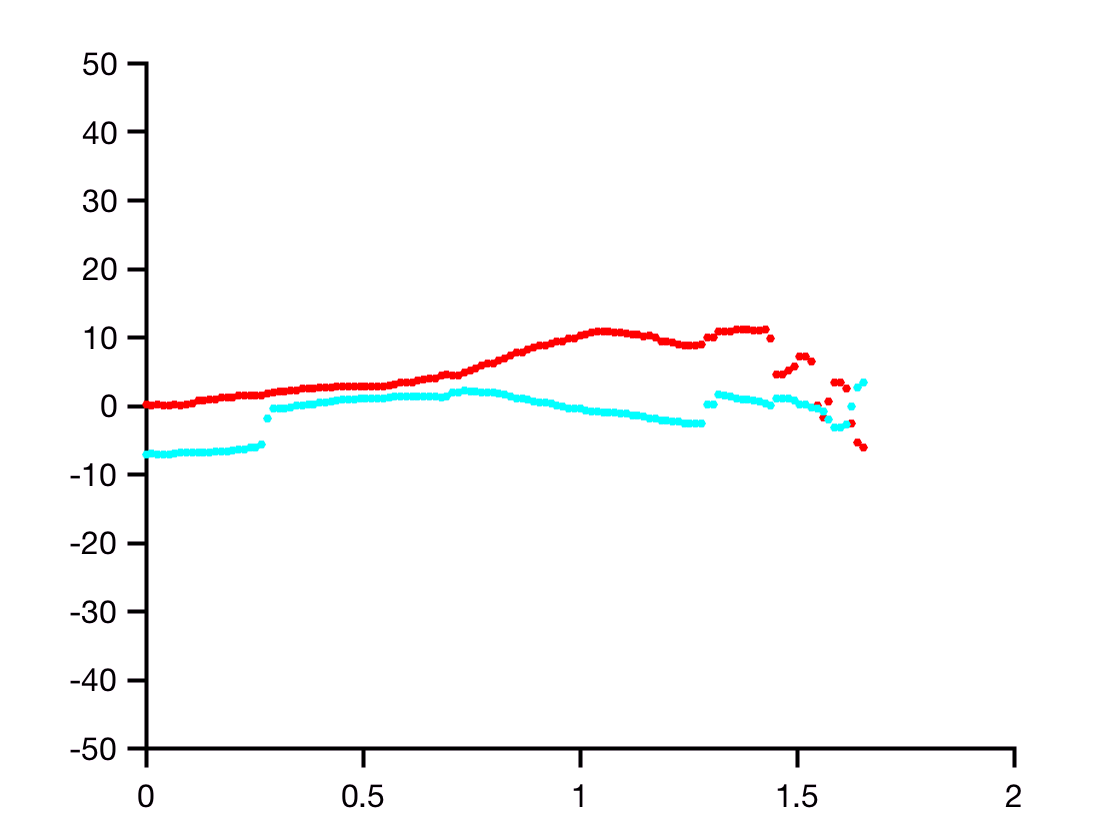

figure(1)
hold on

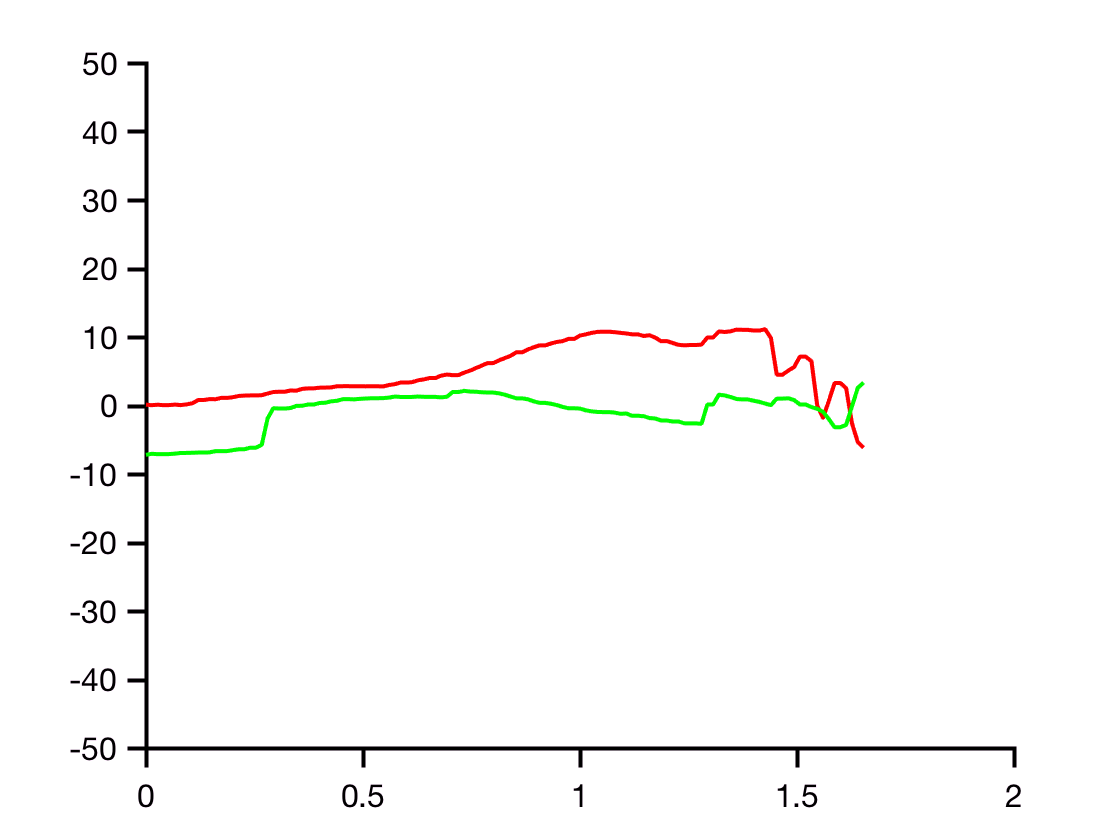

cla
time_fr = [0, cumsum(diff(etData.frameTime_fr(fr)))];
plot(time_fr,eihAzimuthDeg_fr(fr),'r')
plot(time_fr,eihElevationDeg_fr(fr),'g')
ylim([-50,50])

Lets try the same figure, but using "scatter"

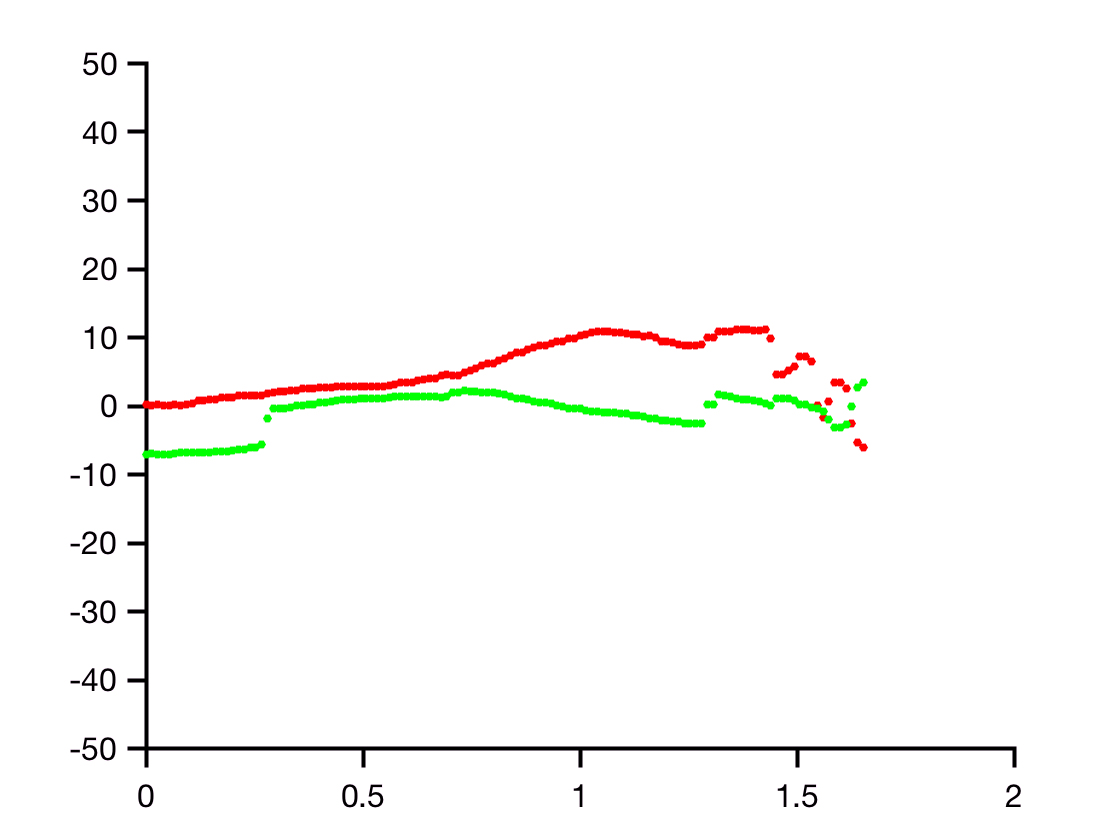

figure(1)
hold on

cla
time_fr = [0, cumsum(diff(etData.frameTime_fr(fr)))];
scatter(time_fr,eihAzimuthDeg_fr(fr),20,'Filled','MarkerFaceColor','r')
scatter(time_fr,eihElevationDeg_fr(fr),20,'Filled','MarkerFaceColor','c')
ylim([-50,50])

Uohoh, missing data! Remember, plot connects datapoints, possibly leading to unnoticed dropouts. We should probably inspect the track quality to better understand what's going on here...